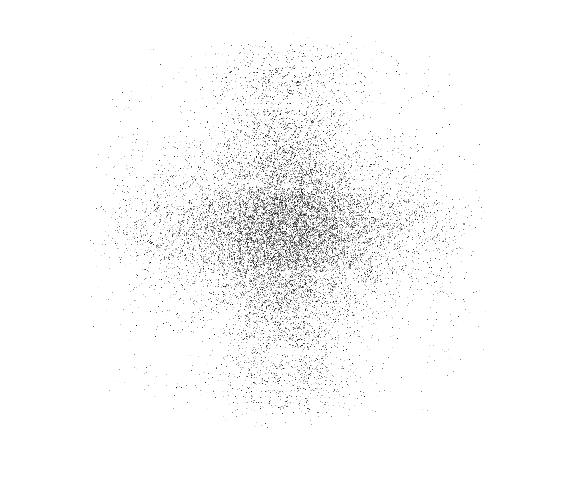

clearvars
close all
% ========================================================
Img = imread('bld.tif');
Img = im2double(Img);

F_img = fft2(Img);
ABS = abs(F_img);
imshow(ABS)

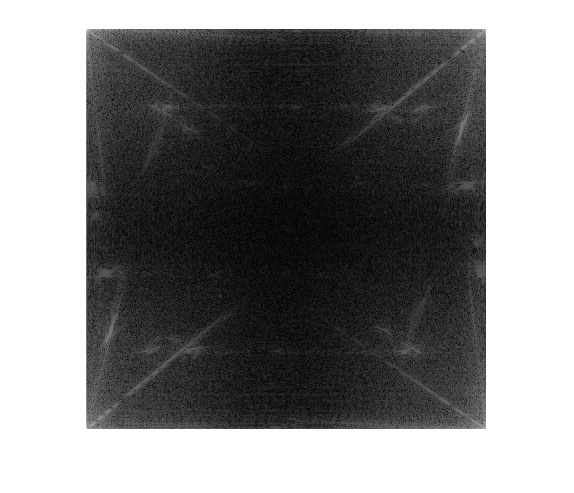

% imshow(double(ABS), [0 255])

imshow(log(1+abs(F_img)),[])

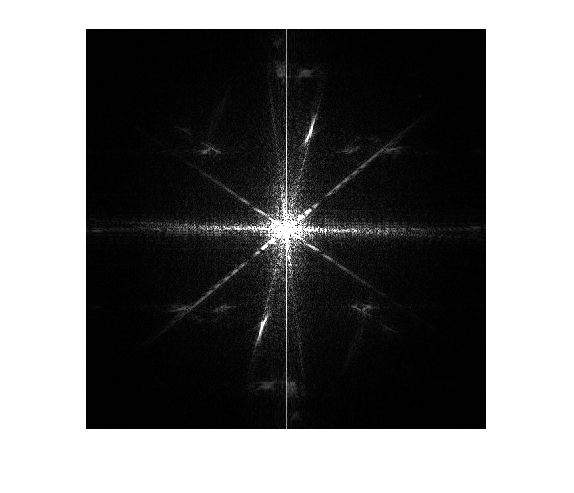


% ---------------------------------------
Fc_img = fftshift(F_img);
imshow(double(abs(Fc_img)), [0 255])

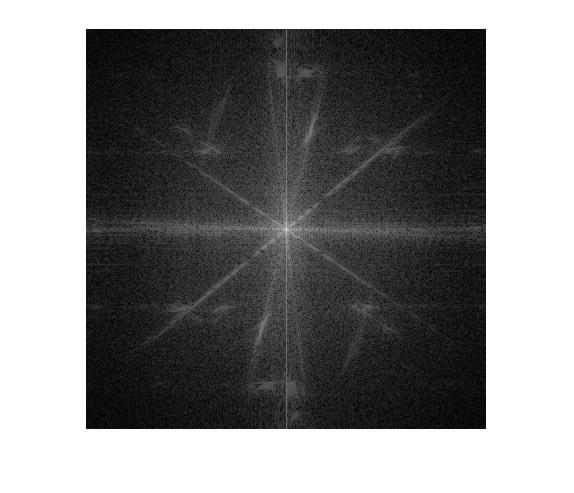

imshow(log10(1+abs(Fc_img)), [])

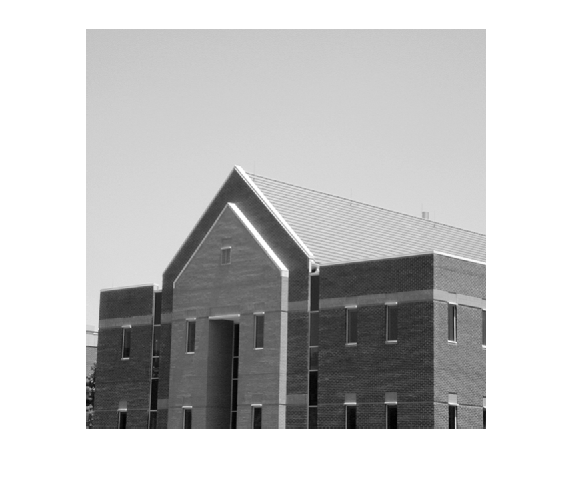


% ---------------------------------------
Org = ifft2(ifftshift(Fc_img));
imshow(Org)

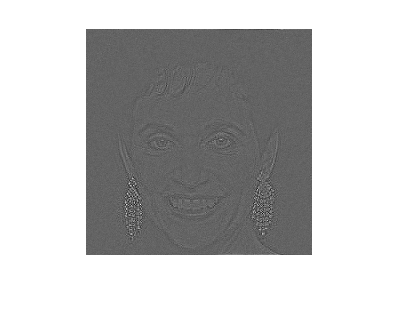

% _______________ About Phase and Magnitude _______________________
close all
clearvars
% ===================================================

im = rgb2gray(imread('Woman.jpg'));
im = im2double(im);
F = fft2(im);
Phase = angle(F);
imshow(ifft2(exp(i*Phase)), [])

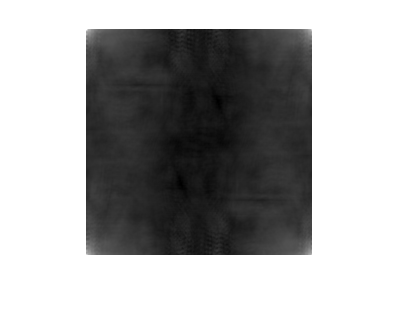

imshow(log10(1+ifft2(abs(F))), [])

% _______________________ FILTERING ____________________________
close all
clearvars
% =======================================

img = imread('a.tif');
img = im2double(img);

% ---------------------------------------

imshow(img), title('Original Image')
[r, c] = size(img);
Mask = ones(r, c);

uc=floor(c/2)+1;
vc=floor(r/2)+1;

% Ideal filtering
% __________________________HighPass_____________________________
D0 = 50;
for i = 1:r
    for j = 1:c
        if sqrt((j-uc)^2+(i-vc)^2) <= D0
            Mask(i,j)=0;
        end
    end
end

F = fftshift(fft2(img));
Filter = F .* Mask;
Output_IHP = ifft2(ifftshift(Filter));

imshow(Output_IHP, []), title('IHP')

% ____________________LowPass Filtering: Ideal__________________________

LP = 1 - Mask;
F = fftshift(fft2(img));
Filter = F .* LP;
Output_ILP = ifft2(ifftshift(Filter));

imshow(Output_ILP, []), title('ILP')

% --------------------------------------------
% ______________________Gaussian____________________
D0 = 50;
GL_filt=zeros(r,c);
for i=1:r
   for j=1:c
      GL_filt(i,j)=exp(-1.*((j-uc)^2+(i-vc)^2)./(2.*D0^2));
   end
end

F = fftshift(fft2(img));
Filter = F .* GL_filt;
Output_G = ifft2(ifftshift(Filter));
imshow(Output_G, []), title('Gaussian')

% -------------------------------------------
% _______________ Butterworth-low pass_______________
n = 2; 
D0 = 10;
BL_filt=zeros(r,c);

for i=1:r
   for j=1:c
      BL_filt(i,j)=1./((1+sqrt((j-uc)^2+(i-vc)^2)./D0)).^2*n;
   end
end

F = fftshift(fft2(img));
Filter = F .* BL_filt;
Output_BL = ifft2(ifftshift(Filter));
imshow(Output_BL, []), title('BL')
%% --------------------------------------------------------------------------

% ____________________Butterworth-high pass_____________________

BH_filt=zeros(r,c);
for i=1:r
   for j=1:c
      BH_filt(i,j)=1./((1+D0./sqrt((j-uc)^2+(i-vc)^2))).^2*n;
   end
end

F = fftshift(fft2(img));
Filter = F .* BH_filt;
Output_BH = ifft2(ifftshift(Filter));
imshow(Output_BH, []), title('BH')
mesh(BH_filt)
colormap(gray)


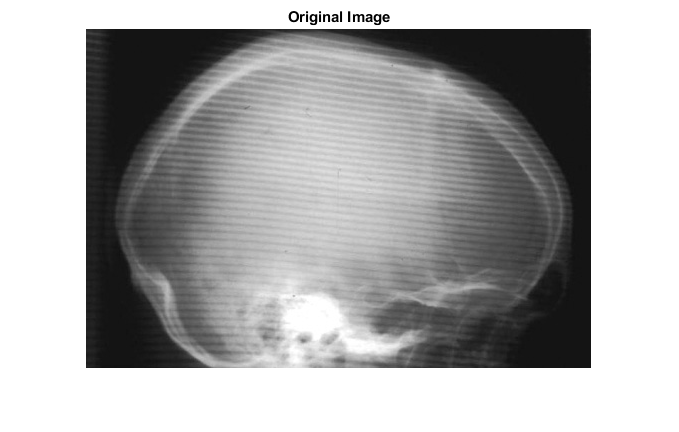

%____________ Periodic Noise Filtering _____________
close all
clearvars
% ===============================================

im = imread('skull.jpg');
im = im2double(im);
[r, c] = size(im);

imshow(im), title('Original Image')

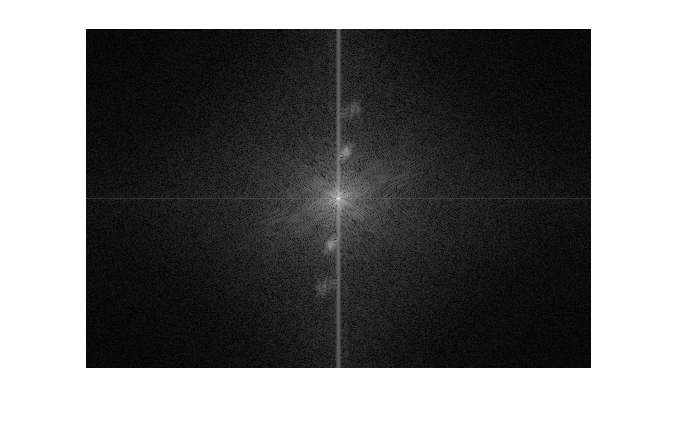


F = fftshift(fft2(im));
imshow(log(1+abs(F)), [])

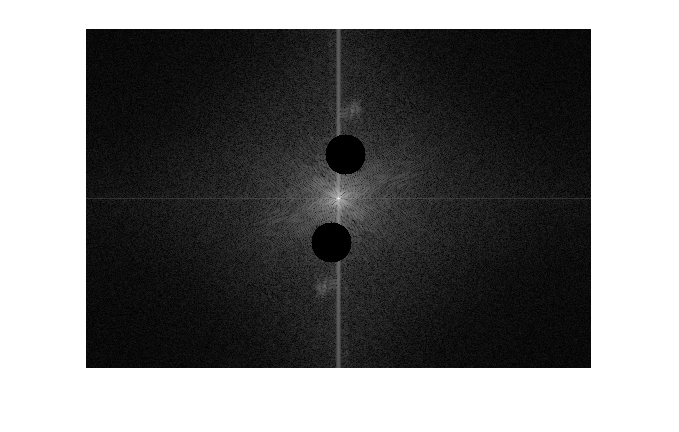


filt = NOTCH(r, c, 260, 126, 20);
imshow(log(1+abs(filt.*F)), [])

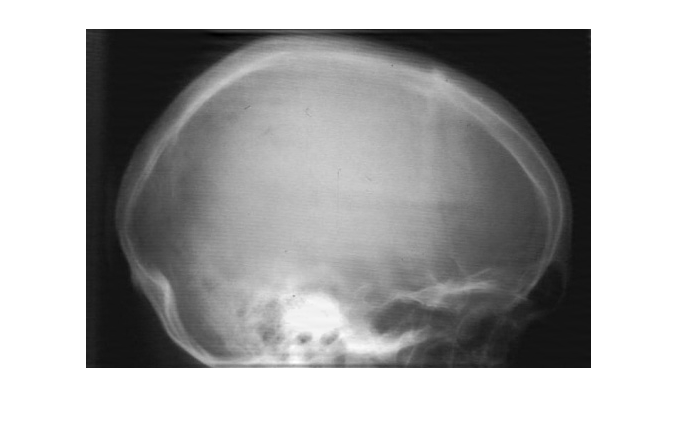

img = ifft2(ifftshift((filt .* F)));
imshow(img, [])

function filt = NOTCH(R, C, U0, V0, D0)
filter = ones(R, C);
for i = 1:R
    
    for j = 1:C
       if sqrt((j-U0)^2+(i-V0)^2) <= D0
           filter(i, j) = 0;
       end
    end
end

filt = filter.*rot90(filter, 2);
end